Příklady k Procvičení:

clear all;
close all;

# Teorie odhadu

## 1. Bodový odhad

Příklad 2:Mějte data 0.1; 0.2; 0.3; … ; 0.8; 0.9 a 1. Vypočtěte vyběrovou střední hodnotu, rozptyl , směrodatnou odchylku a výběrovou šikmost. Jak se změní tyto charakteristiky, jestliže data budou vynásobena 10.

x = 0.1:0.1:1;
y = 10*x;
strhod_x=mean(x)

strhod_x = 0.5500

strhod_y=mean(y)

strhod_y = 5.5000


rozpt_x=var(x)

rozpt_x = 0.0917

rozpt_y=var(y)

rozpt_y = 9.1667


smodch_x=std(x)

smodch_x = 0.3028

smodch_y=std(y)

smodch_y = 3.0277


sikmost_x=kurtosis(x)

sikmost_x = 1.7758

sikmost_y=kurtosis(y)

sikmost_y = 1.7758


spicatost_x=skewness(x)

spicatost_x = -5.2709e-16

spicatost_y=skewness(y)

spicatost_y = 0

## 2. Intervalový odhad střední hodnoty normálního rozdělení

Příklad 3: Deset balíčků mouky pocházející z balícího stroje mělo hmotnost v gramech: 987, 1001, 993, 994, 993, 1005, 1007, 999, 995 a 1002. Sestrojte:

- 95% interval spolehlivosti pro střední hodnotu,

- 90% interval spolehlivosti pro střední hodnotu,

- 95% interval spolehlivosti pro minimální hmotnost. 

data = [987,1001,993,994,993,1005,1007,999,995,1002];
%a)
[h,p,ci]=ttest(data,mean(data),0.05,'both')

h = 0

p = 1

ci = 1.0e+03 *

    0.9931    1.0021


%a)
[h,p,ci]=ttest(data,mean(data),0.1,'both')

h = 0

p = 1

ci = 1.0e+03 *

    0.9940    1.0012


%a)
[h,p,ci]=ttest(data,mean(data),0.05,'right')

h = 0

p = 0.5000

ci =   993.9830       Inf


Příklad 4: Z 12 pozorování doby trvání montážní operace byl zjištěn průměr 44 s a směrodatná odchylka 4 s. Sestrojte 90% interval spolehlivosti pro očekávanou délku operace, jestliže daná operace má normální rozdělení.

Protože nemáte naměřená data, musíte počítat dle vzorců z přednášek. 

n = 12;
x = 44;
s = 4;
alfa = 0.1;
vysl(1) = x - (s/sqrt(n))*tinv(1-alfa/2,n-1);
vysl(2) = x + (s/sqrt(n))*tinv(1-alfa/2,n-1);
vysl

vysl =    41.9263   46.0737


Příklad 5: Naměřili jsme 10 údajů o životnosti žárovky: 380, 402, 408, 412, 454, 459, 472, 481, 491, 502 hodin. Odhadněte, zda data jsou z normálního rozdělení (například pravděpodobnostním papírem) a dale určete 95% intervalový odhad střední hodnoty životnosti žárovky. Určete i 95% jednostranný intervalový odhady pro minimální a maximální odhad střední hodnoty. Interpretujte výsledky. 

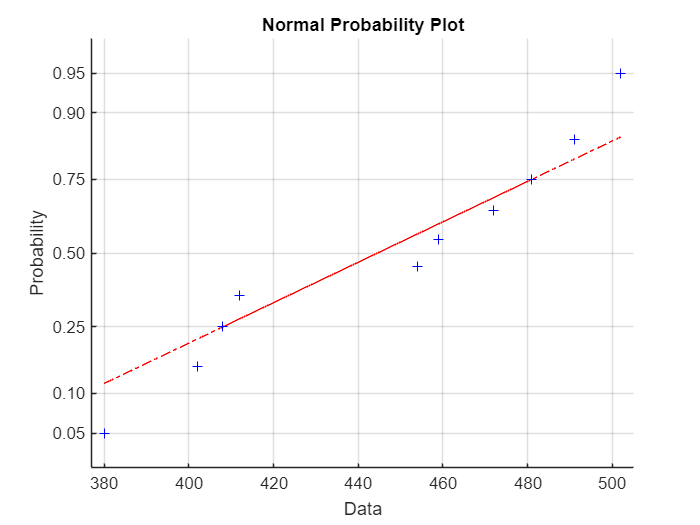

data = [380, 402, 408, 412, 454, 459, 472, 481, 491, 502];
figure
normplot(data) %data jsou z normálního rozdělení

%b)
[h,p,ci]=ttest(data,mean(data))

h = 0

p = 1

ci =   415.7623  476.4377


%c)
[h,p,ci]=ttest(data,mean(data),0.05,'right')

h = 0

p = 0.5000

ci =   421.5162       Inf


%d)
[h,p,ci]=ttest(data,mean(data),0.05,'left')

h = 0

p = 0.5000

ci =       -Inf  470.6838


Příklad 6: V prodejně si udělali průzkum, kolik zákazníků přijde do obchodu během jednoho dne. Byly zjištěny následující data:

 x=[541,574,585,596,612,618,632,641,654,671,681,692,711,713,718,719,754,796,812,815,835,858];

Ověřte, že data jsou z normálního rozdělení. Zjistěte 99% interval spolehlivosti odhadu střední hodnoty. 

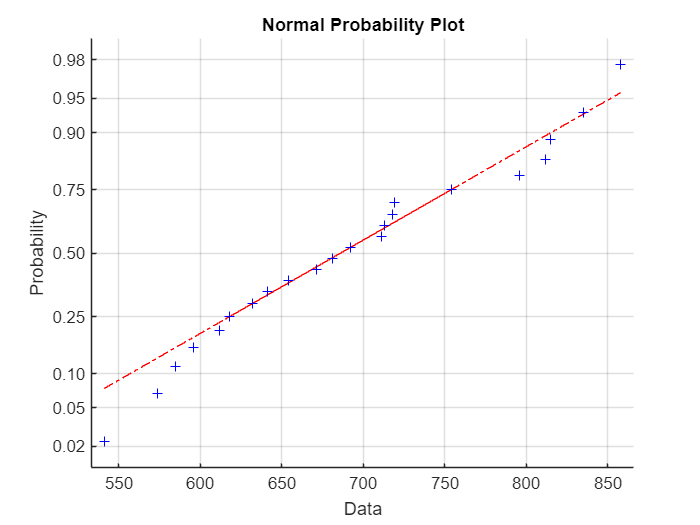

x=[541,574,585,596,612,618,632,641,654,671,681,692,711,713,718,719,754,796,812,815,835,858];
figure
normplot(x) %data jsou z normálního rozdělení

[h,p,ci]=ttest(x,mean(x),0.01)

h = 0

p = 1

ci =   637.5711  746.7926


Příklad 7: Automat vyrábí pístové kroužky o daném průměru. Při kontrole kvality bylo náhodně vybráno 80 kroužků a zjištěna střední hodnota průměru 12.01 mm. A dále vypočtena směrodatná odchylka jejich průměru 0.04 mm. Určete 95% oboustranný intervalový odhad střední hodnoty. Uvažujte dva případy a) směrodatná odchylka je definována na 0.04 mm, b) směrodatná odchylka byla vypočtena 0.04 mm. Odůvodněte rozdíl výsledků. 

(Předpokládejte, že průměr pístových kroužku lze modelovat pomocí normálního rozdělení.)

n = 80;
x = 12.01;
s = 0.04;
alfa = 0.05

alfa = 0.0500

vysl_a(1) = x-(s/sqrt(n))*norminv(1-alfa/2,0,1);
vysl_a(2) = x+(s/sqrt(n))*norminv(1-alfa/2,0,1);
vysl_a

vysl_a =    12.0012   12.0188


vysl_b(1) = x-(s/sqrt(n))*tinv(1-alfa/2,n-1);
vysl_b(2) = x+(s/sqrt(n))*tinv(1-alfa/2,n-1);
vysl_b

vysl_b =    12.0011   12.0189


## 3. Intervalový odhad rozptylu normálního rozdělení

Příklad 8: Deset balíčků mouky pocházející z balícího stroje mělo hmotnost v gramech: 987, 1001, 993, 994, 993, 1005, 1007, 999, 995 a 1002. Sestrojte 

- 95% interval spolehlivosti pro rozptyl a směrodatnou odchylku hmotnosti. 

- 95% jednostranný interval spolehlivosti pro odhad maximální hodnoty rozptylu.

x = [987,1001,993,994,993,1005,1007,999,995,1002];
%a)
[h,p,ci]=vartest(x,var(x))

h = 0

p = 0.8745

ci =    18.4200  129.7591


std_ci=sqrt(ci)

std_ci =     4.2919   11.3912



%b)
[h,p,ci]=vartest(x,var(x),0.05,'left')

h = 0

p = 0.5627

ci =          0  105.3799


Příklad 9: U 100 náhodně vybraných výrobků činila průměrná hmotnost materiálu 150 g a výběrový rozptyl byl 16 g2. Sestrojte 95% interval spolehlivosti pro očekávanou hmotnost materiálu a jeho rozptyl. 

n = 100;
x = 150;
s2 = 16;
alfa = 0.05;
vysl_p(1) = x - (sqrt(s2)/sqrt(n))*tinv(1-alfa/2,n-1);
vysl_p(2) = x + (sqrt(s2)/sqrt(n))*tinv(1-alfa/2,n-1);
vysl_p

vysl_p =   149.2063  150.7937



vysl_r(1) = ((n-1)*s2)/chi2inv(1-alfa/2,n-1);
vysl_r(2) = ((n-1)*s2)/chi2inv(alfa/2,n-1);
vysl_r

vysl_r =    12.3343   21.5918


## 4. Intervalový odhad relativní četnosti

Příklad 10: Při provádění průzkumu 400 respondentů uvedlo 12 %, že by volilo Stranu mírného pokroku v mezích zákona. Vypočtěte 95% interval spolehlivosti pro očekávanou relativní četnost. Jak se změní interval spolehlivosti, jestliže se budeme ptát 1600 respondentů. 

Zdůvodněte, proč je šířka intervalu u 1600 respondentů poloviční, oproti 400 respondentů. 

n = 400;
p = 0.12;
vysl_a(1) = p -sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1);
vysl_a(2) = p +sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1);
vysl_a

vysl_a =     0.0882    0.1518


n = 1600;
vysl_b(1) = p -sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1);
vysl_b(2) = p +sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1);
vysl_b 

vysl_b =     0.1041    0.1359


Příklad 11: Při kontrole data spotřeby určitého druhu masové konzervy ve skladech produktů masného průmyslu bylo náhodně vybráno 320 z 20 000 konzerv a zjištěno, že 59 z nich má prošlou záruční lhůtu. Stanovte se spolehlivostí 95% intervalový odhad podílu konzerv s prošlou záruční lhůtou. A dále 95 % intervalový odhad počtu konzerv s prošlou záruční lhůtou. 

p = 59/320;
n = 320;
alfa = 0.05;
vysl_p(1)=p -sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1);
vysl_p(2)=p +sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1)

vysl_p =     0.1419    0.2269



vysl_n(1)=vysl_p(1)*20000;
vysl_n(2)=vysl_p(2)*20000

vysl_n = 1.0e+03 *

    2.8377    4.5373


## 5. Rozsah výběru

Příklad 13: Při odhadu volebních výsledků chceme, aby šířka intervalu volebního výsledku mající odhadem 20 % hlasů byla maximálně 2 %. Určete rozsah výběru pro 95% intervalový odhad. 

sirka = 0.02;
p = 0.2;
alfa = 0.05;
rozsah = (4*p*(1-p)/sirka^2)*norminv(1-alfa/2)^2

rozsah = 6.1463e+03

Příklad 14: Ze zadání příkladu 13 proveďte diskuzi, při jaké pravděpodobnosti volebního výsledku strany musí být rozsah největší, a kdy naopak nejmenší. Ověřte grafem výsledek.

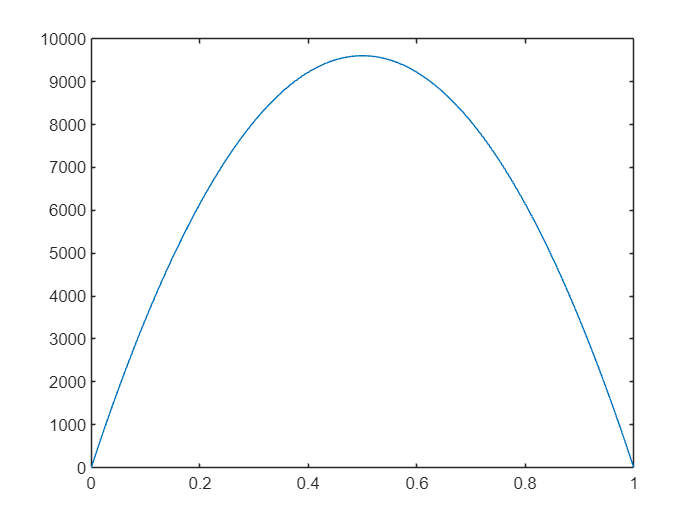

p = 0:0.001:1;
rozsah = (4.*p.*(1-p)./sirka.^2).*norminv(1-alfa./2).^2;
figure
plot(p, rozsah)

max(rozsah)

ans = 9.6036e+03

Příklad 14a: Jak velký by měl být rozsah výběru, jestliže chceme, aby 95% intervalový odhad měl šířku intervalu relativní četnosti menší než 0.01. 

clear rozsah
alfa = 0.05;
sirka = 0.01;
p = 0.5;
rozsah = (4*p*(1-p)/sirka^2)*norminv(1-alfa/2)^2

rozsah = 3.8415e+04

## 6. Intervalový odhad mediánu

Příklad 15: Životnost výrobku je popsána exponenciálním rozdělením. Byly zjištěny následující data doby do poruchy: 

x=[37,61,98,135,162,194,222,235,256,287,317,345,400,412,484,495,510,528,612,711,787,843,911,987,1014,1218,1512] hodin. 

Opticky ověřte, že data nejsou z normálního rozdělení, ale z exponenciálního. Určete 95% intervalový odhad mediánu.

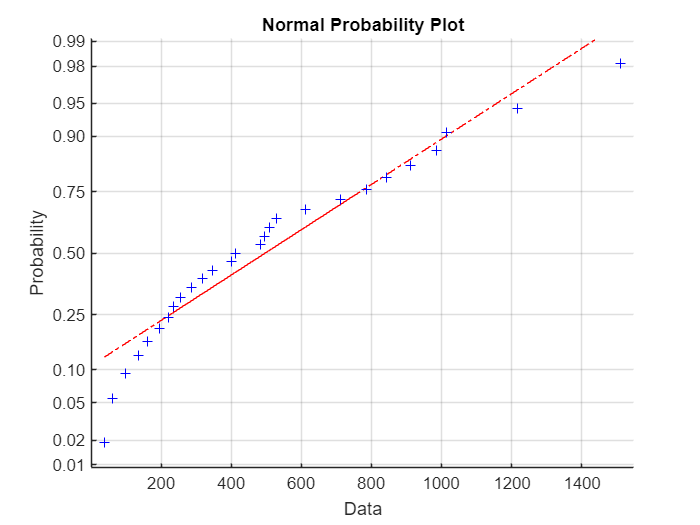

x=[37,61,98,135,162,194,222,235,256,287,317,345,400,412,484,495,510,528,612,711,787,843,911,987,1014,1218,1512];
figure
normplot(x) %data nejsou z normálního rozdělení

q25 = quantile(x,0.25);
q75 = quantile(x,0.75);
n = length(x);
vysl(1) = median(x) - 1.57*(q75-q25)/sqrt(n);
vysl(2) = median(x) + 1.57*(q75-q25)/sqrt(n)

vysl =   248.0099  575.9901


Příklad 16: Vygenerujte si 10000 dat z normálního rozdělení s parametry $\mu =170,\ \sigma =50$. Data jsou symetrická kolem střední hodnoty. Vypočítejte 95 % odhad střední hodnoty, jestliže víte, že data jsou z normálního rozdělení. A obdobně vypočtěte 95% odhad mediánu, jestliže informaci o typu rozdělení nemáte. 

Odhadněte, proč je šířka intervalu přibližně stejná?

x = normrnd(170,50,1,10000);
%a)
[h,p,ci] = ttest(x)

h = 1

p = 0

ci =   169.3427  171.3149


%b)
q25 = quantile(x,0.25);
q75 = quantile(x,0.75);
n = length(x);
med(1) = median(x)-1.57*(q75-q25)*sqrt(n);
med(2) = median(x)+1.57*(q75-q25)*sqrt(n) 

med = 1.0e+04 *

   -1.0494    1.0835


## 7. Intervalový odhad parametrů spojitých rozdělení

Příklad 16a: Doba do poruchy nedegradujícího výrobku je popsána exponenciálním rozdělením. Prováděla se zkouška 50 výrobků po dobu 1000 hodin. Po poruše nebyly výrobky nahrazovány. Bylo zjištěno 10 poruch, u ostatních 40 výrobků byla zkouška ukončena v čase 1000 hodin. Určete parametr exponenciálního rozdělení a jeho 95% intervalový odhad. 

Tporuch=[80,160,240,320,400,560,720,800,900,960]   

t=[80,160,240,320,400,560,720,800,900,960];
alfa = 0.05;
cens(1:length(t)) = 0;
cens(end+1)=1;
freq(1:length(t))=1;
freq(end+1)=40;
t(end+1)=1000;
[par,io] = expfit(t,alfa,cens,freq)

par = 4514

io = 1.0e+03 *

    2.6421
    9.4132


Příklad 16b: Rozšířené zadání příkladu z kap. 5, př. 21. 

Zjistěte z dat o poruchovosti výrobku, které jsou uloženy v souboru P0716b.mat, parametry Weibullova rozdělení a jejich 95% intervalový odhad. 

x = importdata("P0716b.mat");
alfa = 0.05;
[par,io] = wblfit(x,alfa)

par =   269.4155    5.4606


io =   266.2033    5.2152
  272.6664    5.7176


## 8. Intervalový odhad poměrů rozptylů dvou výběrů s normálním rozdělením

Příklad 17: Stroj vyrábějící komponenty potřebuje jednou za čas setřídit. Při testování několika výrobků po 20 hodinách nepřetržitého provozu jsme obdrželi následující hodnoty určitého rozměru. Obdobně jsme testovali také po 50 hodinách nepřetržitého provozu. 

x20=[3.96,4.03,4.07,4.12,4.16,4.18,4.20,4.22,4.23,4.24,4.24,4.25,4.29,4.32,4.35,4.38,4.41,4.44];

x50=[4.02,4.07,4.11,4.16,4.22,4.28,4.32,4.36,4.40,4.42,4.46,4.48,4.51,4.52,4.54,4.58,4.62,4.73];

Velikost rozptylu u stroje ukazuje, zda je třeba stroj setřídit či nikoliv. Zjistěte 99% intervalový odhad podílů rozptylu.

x20=[3.96,4.03,4.07,4.12,4.16,4.18,4.20,4.22,4.23,4.24,4.24,4.25,4.29,4.32,4.35,4.38,4.41,4.44];
x50=[4.02,4.07,4.11,4.16,4.22,4.28,4.32,4.36,4.40,4.42,4.46,4.48,4.51,4.52,4.54,4.58,4.62,4.73];
alfa = 0.01;
rozdil=var(x20)/var(x50)

rozdil = 0.4141

[h,p,ci]=vartest2(x20,x50,alfa)

h = 0

p = 0.0778

ci =     0.1117    1.5351


## 9. Intervalový odhad rozdílů středních hodnot dvou výběrů s normálním rozdělením

Příklad 19: V roce 1980 jsme se dostali rychlíkem z Prahy do Brna za t1980=[243,251,257,257,259,261,263,265,284, 293] minut. Obdobně v roce 2015 jsme stejnou cestu absolvovali za t2015=[191,193,193,195,195,195,197,198,199,202,202,203,204,205,207,208] minut. Zjistěte 99% intervalový odhad zrychlení cesty.

t1980=[243,251,257,257,259,261,263,265,284, 293];
t2015=[191,193,193,195,195,195,197,198,199,202,202,203,204,205,207,208]

t2015 =    191   193   193   195   195   195   197   198   199   202   202   203   204   205   207   208


alfa = 0.01;
[h,p,ci]=ttest2(t1980,t2015,alfa)

h = 1

p = 3.1342e-14

ci =    52.8176   75.4074


## 10. Intervalový odhad pro rozdíl relativních četností dvou výběrů

Příklad 21: HDD dvou velkých výrobců - DISK a EMEM byly podrobeny zkoušce kvality. HDD obou výrobců jsou baleny po 20 kusech. Ve 40 balících firmy DISK bylo nalezeno 24 vadných HDD, ve 30 balíčcích EMEM bylo nalezeno 14 vadných HDD. Se spolehlivostí 0,95 určete intervalový odhad rozdílu relativních četností (procent) vadných HDD v celkové produkci firem DISK a EMEM.

nDISK=800;
nEMEM=600;

porDISK=24;
porEMEM=14;

pDISK=porDISK/nDISK;
pEMEM=porEMEM/nEMEM;

p=(porDISK+porEMEM)/(nDISK+nEMEM);

alfa = 0.05;

roz(1)=(pDISK-pEMEM)-sqrt(p*(1-p)*(1/nDISK+1/nEMEM))*norminv(1-alfa/2,0,1);
roz(2)=(pDISK-pEMEM)+sqrt(p*(1-p)*(1/nDISK+1/nEMEM))*norminv(1-alfa/2,0,1)

roz =    -0.0105    0.0239


Příklad 22: Stranu mírného pokroku v mezích zákona by v roce 2020 volilo 60 z 845 respondentů. Obdobný průzkum proběhl i v roce 2021 s výsledkem: 57 z 541 respondentů. Určete intervalový odhad na hladině významnosti 95 %, o kolik se zvýšila podpora této strany. 

n20 = 845;
a20 = 60;
p20 = a20/n20;
n21 = 541;
a21 = 57;
p21 = a21/n21;
p = (a20+a21)/(n20+n21);

vysl(1)=(p21-p20)-sqrt(p*(1-p)*(1/n20+1/n21))*norminv(1-alfa/2,0,1);
vysl(2)=(p21-p20)+sqrt(p*(1-p)*(1/n20+1/n21))*norminv(1-alfa/2,0,1)

vysl =     0.0044    0.0644
